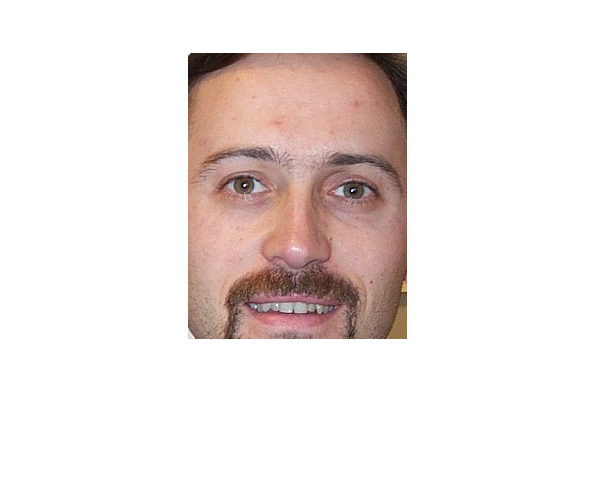

addpath('functions');
addpath('Images\DB1\');
% Main-file

% PART 1 (purpose to find eyes)

% Load dataset
test1 = imread("images/DB1/db1_06.jpg");


% Get the size of the original image
[height, width, ~] = size(test1);

% Define the percentage of pixels to crop (e.g., 20%)
cropPercentage = 20;

% Calculate the number of pixels to crop for width and height
cropWidth = round(width * (cropPercentage / 100));
cropHeight = round(height * (cropPercentage / 100));

% Calculate the crop region [x, y, width, height]
cropX = cropWidth + 1; % Start from the (cropWidth + 1)-th pixel to keep the right side
cropY = cropHeight + 1; % Start from the (cropHeight + 1)-th pixel to keep the bottom side
cropWidth = width - 2 * cropWidth;
cropHeight = height - 2 * cropHeight;

% Crop the image using imcrop
croppedImage = imcrop(test1, [cropX, cropY, cropWidth, cropHeight]);

imshow(croppedImage)

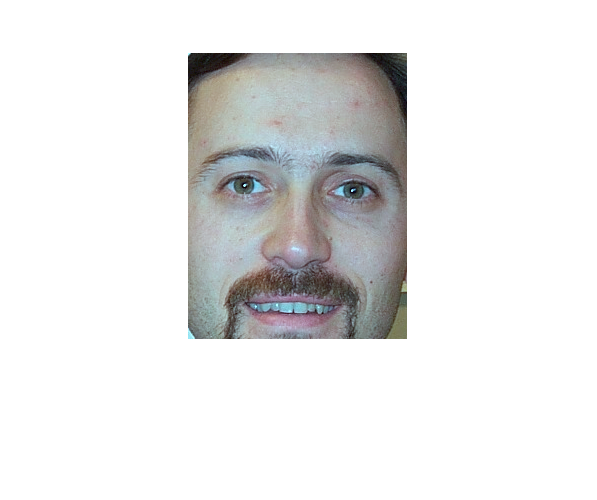


%%%%%% Lighting compensation - Gray World & White Patch %%%%%
GW = GrayWorld(croppedImage);
imshow(GW)

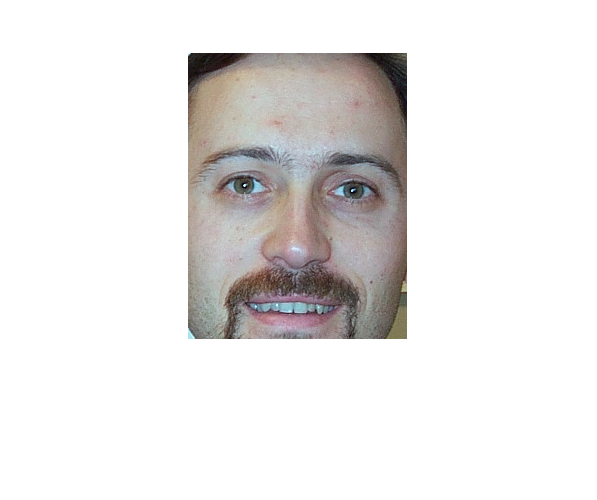

WP = WhitePatch(croppedImage);
imshow(WP)

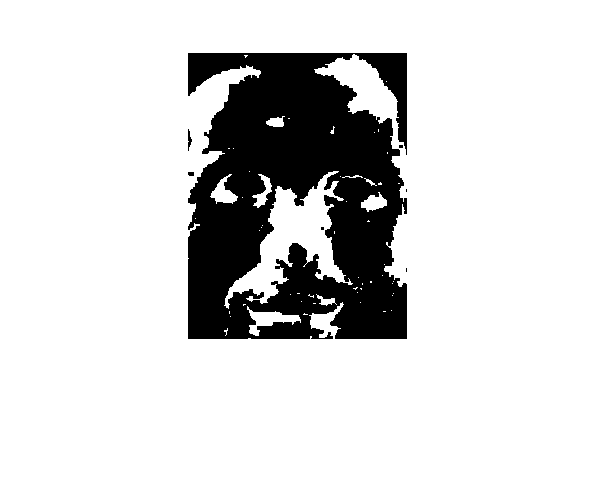



%%%%%%% Color Space + FaceMask  %%%%%%%%%%%%%%%%%%%%%
testFM = FaceMask(WP);
imshow(testFM)

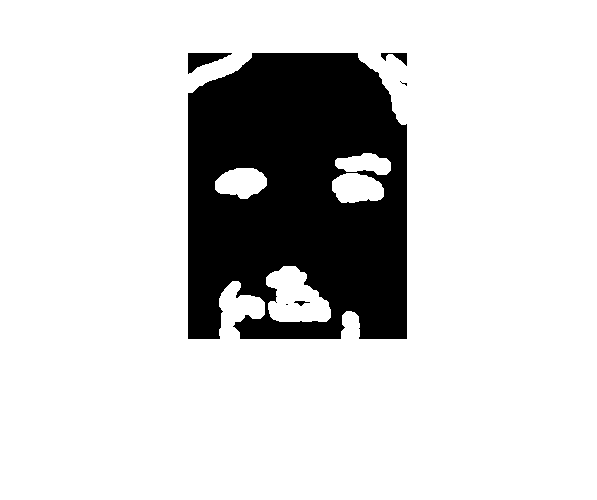


%%%%%%%%%%%% Eye map: Chrominance & Luminance %%%%%%%%%%%%
[binaryEyeMap, circle, randii] = EyeMap(WP);
imshow(binaryEyeMap)

circle


circle =

     []



centersStrong5 = circle(1:2,:)

Index in position 1 exceeds array bounds.

radiiStrong5 = randii(1:2)
viscircles(centersStrong5, radiiStrong5,'EdgeColor','b');



%%%%%%%%%%%%% Mouth map? %%%%%%%%%%%%%%%%%%%%%%%%%
MM = MouthMap(WP);
imshow(MM)

%%%%%%%%%%%%%% Face Boundary%%%%%%%%%%%%%%%%%%%%%%%% 
% FB = face_boundary(GW);
% imshow(FB)

%%%%%%%%%%%%%%% Normilization %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%%%%%%%%%%%%%%% Looping through all the images %%%%%%%%%%%%%%%%%%%

% % Specify the folder containing the images
% folderPath = 'Images\DB1\';
% 
% % Get a list of all image files in the folder
% imageFiles = dir(fullfile(folderPath, '*.jpg')); % Change the extension as needed
% 
% % Loop through each image file
% for i = 1:length(imageFiles)
%     % Read the image
%     imagePath = fullfile(folderPath, imageFiles(i).name);
%     img = imread(imagePath);
% 
%     % Apply the GrayWorld & MouthMap/FaceMask function
%     GW = WhitePatch(img);
%     mouthMapResult = MouthMap(GW);
% 
%     % Display the original image and the processed result
%     figure;
%     subplot(1, 2, 1);
%     imshow(img);
%     title('Original Image');
% 
%     subplot(1, 2, 2);
%     imshow(mouthMapResult);
%     title('Thresholded Mouth Map');
% 
%     % Pause to allow for viewing before moving to the next image
%     pause(2);
%     close all;  % Close the figure window for the next iteration
% end